## Programa para a Modelagem da degradação de poliésteres biodegradáveis amorfos (Com a difusão de Cadeia pequena) 

Esse programa tem como intuito realizar o calculo da Massa Molar de um poliester, no caso PLA, ao longo do tempo, considerando a difusão de cadeias pequenas.

## Defnir Variaveis a serem utilizadas

global a GP m b k1 k2 n C0 Ce0 tf k2_ Rs0 t0 dt t1 t2 Rs1 Rs2 Mn1 Mn2 Mn X1 X2


## Ler a entrada do Usuario

polimero = input('Qual polímero está sendo analisado? ', 's');

polimero = 'PLA'

massa_molar_media = input('Qual é a massa molar média do polímero? ');
tf = input('Quantas Semanas vão ser avaliadas? ');

tf = 25

## Definir as Informações especificas de Cada Polimero

if strcmpi(polimero, 'PLA')
    massa_molar_mere = 144.14;  % Massa molar do mero do PLA (ácido láctico)
    numero_ligacoes_ester = 1;  % Número de ligações éster por mero do PLA
    densidade_polimero = 1.24;  % Densidade do PLA
    k1 = 5E-4;                  % Constante de taxa de hidrólise para reação não catalítica; 1/semana
    k2_ = 0.0539;               % Constante de taxa de hidrólise para reação autocatalítica; 1/semana 
else
    error('Polímero não suportado. Por favor, escolha PLA.');
end

## Calcular o grau de Polimerizacao (GP)

GP = massa_molar_media/massa_molar_mere;

## Calcular o numero total de ligações éster por  unidade de volume (Ce0) 

Ce0 = (densidade_polimero/massa_molar_mere)*numero_ligacoes_ester;
Ccadeia = Ce0/GP;               % Número de cadeias poliméricas por unidade de volume
C0 = 0*Ce0;                     % Concentração inicial normalizada de grupos finais –COOH

## Definir Constantes que serão utilizadas para o integrador do Matlab 

n = 0.5;                        % Expoente de dissociação ácida de grupos –COOH
k2 = (Ce0^n)*k2_;               % Constante de taxa de hidrólise para reação autocatalítica normalizada; 1/semana
m = 4;                          % DP médio das cadeias curtas; adimensional
a = 0.4;                        % Parâmetros empíricos para produção de cadeia curta
b = 1;                          % parâmetros empíricos para produção de cadeia curta
X1 = 0;                         % Parâmetros de particionamento para as cadeias longas para atuar como catalisadores, adimensionais.
X2 = 1;                         % Parâmetros de particionamento para as cadeias curtas para atuar como catalisadores, adimensionais.

## Chamar o Integrador e Calcular a Taxa de dissociação e Massa Molar

Rs0 = 0;                        % Numero de cadeias quebradas no inicio
t0 = 0;                         % Tempo inicial
dt = 1;                         % Passo de integração


### Integrador do Matlab

[t1,Rs1]=ode45(@calc_f_Rs_av, [t0 tf], Rs0);


### Calcular Massa Molar

Mn1 = (1 - a*Rs1.^b)./(1+GP.*(Rs1 - (a/m)*Rs1.^b));     % Massa Molar Com Exclusao de Cadeia  

## Plotar 

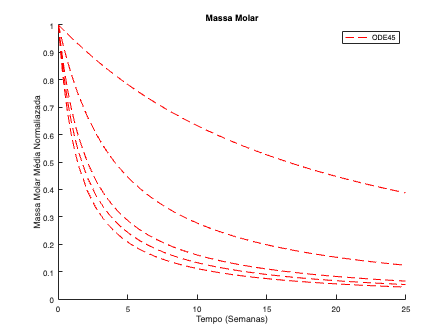

hold on
plot(t1,Mn1,'Color', 'r', 'LineStyle', '--', 'Marker', 'none');
title 'Massa Molar';
xlabel('Tempo (Semanas)');
ylabel('Massa Molar Média Normaliazada');
legend('ODE45');
hold off